# Drainage reorganization

Rivers are mobile and move around in time and space, thereby shaping the landscape around them. Last time we focused on river profiles and how they evolve through time. Today, we want to focus more on the planform geometry of rivers and how river basins change their shape through time. This is not some unimportant theoretical process of nerd ivory tower science. Rivers are the main agents of landscape evolutiion and typical control most aspects of a landscape. Drainage divides separating rivers are by definition always the highest parts of the landscape. Therefore, moving draining divides around has a large effect on climate (orographic effects at drainage divides govern many of our planets large weather patterns), ecology (e.g., separating populations of species through topographic barriers), and hydrology (drainage divide locations determine where the water flows). 

We recently wrote a review article about the migration of drainage divides through time and its implications for life and climate. You can find the article here

[Drainage divide migration and implications for climate and biodiversity | Nature Reviews Earth & Environment](https://www.nature.com/articles/s43017-023-00511-z)

This being said, southwestern Germany is among the best places in the world to study the movement of drainage divides. The whole region went through a major change in river flow patterns over the course of the past few million years. Let's try to uncover this history by just using elevation data.

clc
clear 
close all
DEM =  % load DEM
DEM.Z  % condition DEM that streams don't flow south. Make last row of raster = 2000m elevation 
DEM.Z(DEM.Z == 0) = nan;   % during projection some of the DEM pixels were set to zero though they should be NaN.

### Chi $-\;\chi$

The most used metric to study drainage divide migration is chi. Let's recall the equation 


$$\chi =\int_{\textrm{x0}}^x {\left(\frac{A_0 }{A}\right)}^{\frac{m}{n}} \textrm{dx}\;\ldotp \;$$


A0 is a reference drianage area that is just introduced to keep the units in meters. A0 is typically set to 1m². x0 is the location of base level.

Chi is an integration that moves upstream and while adding the reciprocal of the drainage area. Therefore, chi is like a upstream distance that accounts for the increase in drainage area. 

#### How does chi work?

$\chi$ is used as an indicator of drainage network stability and divide migration. **Can you explain why that would make sense (no worries this is a hard question)?**

Hint: Rivers need discharge/drainage area to erode efficiently. The more discharge/drainage area, the more efficient a stream is at eroding. Also, the steeper a stream the more erosional power it has. 

Chi integates from base level upstream. Therefore, the closer to base level, the lower your chi. If you compare river across a drainage divide, the one that has a shorter flowpath to baselevel will have a **lower chi** value, be steeper, and probably **erode more quickly**. The same argument applies to drainage area. The more drainage area, the more erosion, and the smaller the reciprocal of drainage area, and therefore chi. Chi can be seen as parameter that captures how optimally shaped a drainage basin is.

A long and narrow drainage basin will have high chi and low erosional power. A short and wide basin, the opposite.

#### Assumptions and caveats

As with every scientific method, there are a number of assumptions that go into the calculation. The main assumption is that U and K are constant in space and time. In theory, one could account for U/K variations in the calculation, but these parameters are usually hard to constrain and most people ignore this caveat in a first rough analysis. 

% calculate the flow network
FD = % calculate flow network using carve option
minArea = 5e6; % minimum drainage area for streams
S  = % make stream network
A =  % determine flow accumulation

### Baselevel

For calculating a chi map, we need to choose a common baselevel. This should be the baselevel that your river flow to. Either the sea or a local feature that acts a local baselevel of your river (where rivers switch from erosion to deposition).

Use the slider below and experiment with the baselevel elevation. Can you choose a meaningful baselevel that works for the Rhine and Danube rivers?

baseLevel = 170
DEMb = DEM > baseLevel;
imageschs(DEM,DEMb)
hold on
plot(S)

As you see, it is hard to select a baselevel that works for both rivers in a meaningful way. Why is that so hard here?

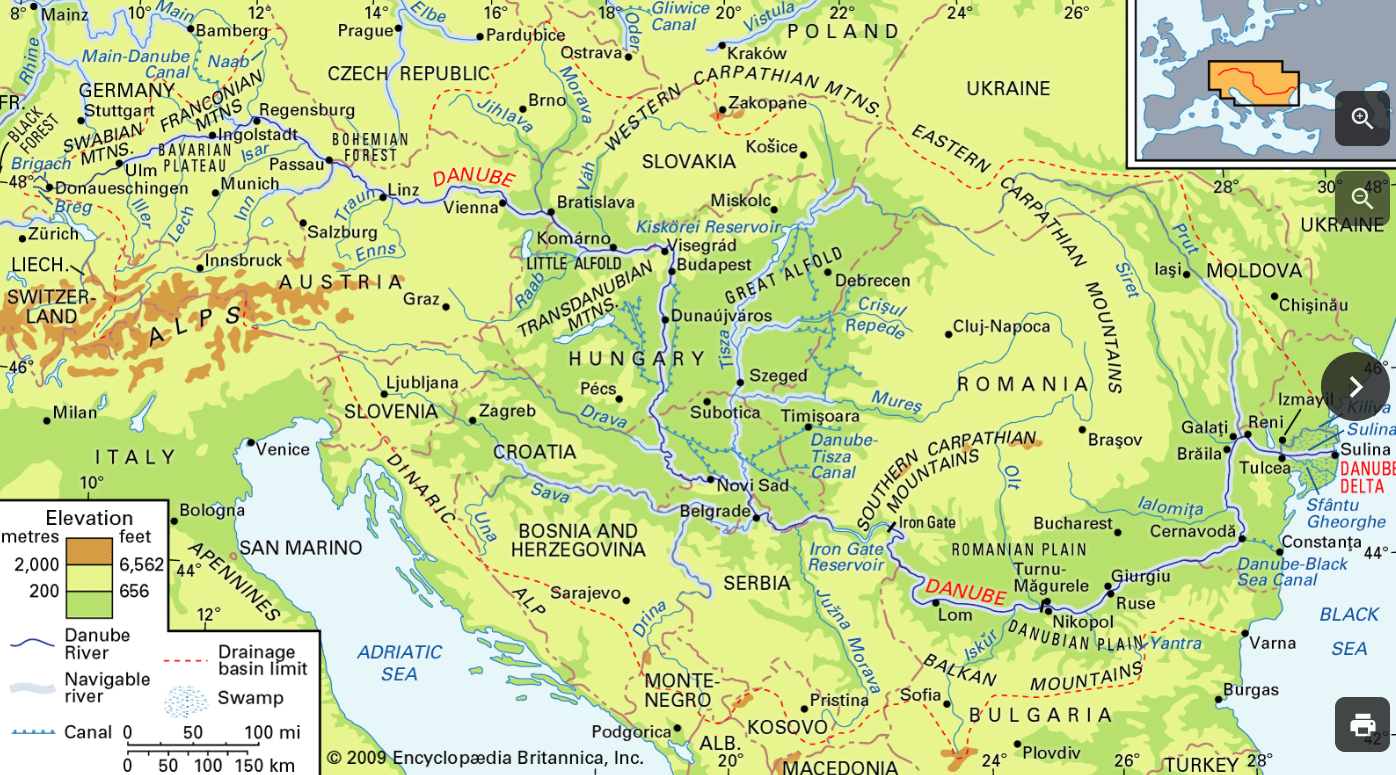

Let's look at the Danube river basin. It is huge and the real first baselevel of the Danube is the depositional Panonian Basin that starts in Vienna. Vienna has about the same elevation as the Upper Rhine Graben. Therefore, in an ideal world you would choose something like 180m elevation as baselevel for the Rhine-Danube comparison. However, then we'd need a huge DEM because we'd need the entire Danube basin until Vienna! This is impractical for your laptops and our course, so we'll need to improvise a bit.

Now we know the best baselevel. Chi is calculated only along the streams, therefore, you need to clip your stream network to the area upstream of your base level. Use the function 'griddedcontour' to make a contour and the 'modfiy' to clip your STREAMobj. Once, you've clipped your stream network you can use  'chitransform'  to calculate chi with your concavity from before.

theta_ref = 0.45;
baseLevel = 180;

Con  = % use 'griddedcontour' to make a contour map with the baseLevel elevation (only one contour)
Con.Z(:,end) = true; % make sure east draining rivers are part of stream network

% extract all stream flowing above the contour line
Schi = % use 'modify' and the 'upstreamto' function together with the contour you just made
% chi  = chitransform(Schi,A,'mn',theta_ref);  % THIS IS HOW YOU'D NORMALLY
% CALCULATE CHI!!! Instead we'll load a precalculated file
chi = load('chi.mat'); chi = chi.chi;

Now, let's plot the chi map to look at potential disequilibrium in the drainage network and potential divide movement. We'll use the roma color map. I suggest you plot the DEM with the "gray" colorbar and then plot the chi values on top with the 'plotc' command. Try it out!

% color maps
cc = flipud(ttscm('roma'));  % load roma color map and reverse it
cg = gray;

h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',cg(1:255,:),'colorbar',false)
% use plotc to plot the stream network colored by chi
% set colormap to cc (roma)
% show colorbar

Rivers with low chi values that are next to rivers with high chi values are likely to eat away drainage area from the high chi basins over time. Can you find such disequilibrium in the drainage network of  southwestern Germany?

Which rivers are eating away area from which other rivers?

Does this pattern connect to observations from the last lecture on river profiles?

Most of the chi maps are plotted similarly to what we've just done. But personally, I find it sometimes hard to really see the disequlibrium. Chi can only be calculated for streams, but there's a trick I use for better visibility, e.g. in this paper, figure 3 [LINK](https://doi.org/10.1016/j.gloplacha.2021.103641). You can project values from the streams onto the hillslopes by reversing the flow routing. This means that a hilllslope pixel simply gets assigned the value of the stream pixel that they eventually drain into. In TT, values that are only stored for stream nodes are referred to as nal (node attribute list). Our chi values are a "nal" but can be projected onto the hillslopes with 'mapfromnal'. Use it to make a chi map!

chiMap = % use 'mapfromnal' to make a GRIDobj of chi values. Use the correct stream network!
D = DIVIDEobj(FD,Schi); % calculate the divides. Use the correct stream network (the one you used for chi)
D =  % calculate the order of the divide to make it look prettier ;)
figure(); 
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,chiMap,'colormap',cc(1:255,:),'colorbar',true)
hold on
plot(D,'limit',[2000 inf],'color','k') % plot divides

Now, this looks much clearer and easier to interpret. You see the main divides and you should be able to pick out where the divide is supposed to move in the future.

So, it seems like the Danube basin is shrinking, as the Rhine/Neckar system is growing over time. What could be driving this change?

- Discussed in lecture and/or _key file

In the west, the Neckar is also shrinking compared to the direct Upper Rhine graben rivers. However, is that a real singal or coud there be another explanation for this chi-contrast? Same is true for the west side of the Upper Rhine Graben.

### Evidence of former shrinking?

The current landscape suggests a strong disequilibrium between Danube and Rhine. These things don't happen over night. Therefore, we can assume that his reorganization process has likely been ging on for a while. Can we see evidence for this hypothesis in the landscape?

Typical signs of river reorganization are windgaps, river elbows.

cc = ttscm('batlow');  % load batlow color map

Quick side note. You can find all scientific color maps included in TT with their names here: [Scientific colour maps – colour-blind friendly and accurate palettes](https://www.fabiocrameri.ch/colourmaps/)

figure(); 
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',cc(1:255,:),'colorbar',true, 'caxis', [0 1300])
hold on
plot(D,'limit',[10e3 inf],'color','k') % plot divides
plotstreamorder(S,'colormap',[0, 0, 0.5],'LineWidth',max([1 2 3 4 5 6 7]/2,1))    % plot stream accroding to Strahler order

Now, take some time to search for sign of river capture. Look alog the Rhine/Neckar—Danube drainage divide. Any signs or reorganization there? Do you also see signs of reorganization in the Neckar basin or the Black Forest? Look for anomoulous river drainage patterns. 

Compare the drainage basin shape of the Danube and the Neckar. What is the obvious difference in shape?

### The Wutach capture

The last episode of the Rhine capturing Danube tributaries, is the Wutach capture that occured about 18'000 years ago. This river capture formed the Wutach gorge. Let's first have a look at the gorge and the drainage network.

figure()
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap','landcolor','colorbar',true, 'caxis', [300 1100])
extent = {[4.3866e+05, 4.7602e+05]},{[5.2739e+06, 5.3062e+06]};
setextent(ex)

Let's extract the river profiles of the Wutach that gained drainage area and the remnant of the Danube that got beheaded. Let's comapre the river profiles. Did they reach a new equilibiurm or are the river profiles still transient? How much erosion happened in Wutach after the capture? Was is a lot or similar to normal erosion rates in the region?

xBlum = 466604;     % x coordinate of Danube channe head at Blumberg
yBlum = 5298930;
ixBlum = % use 'coord2ind' to convert coordinates into IX (linear index) into DEM of Blumberg Danube channel head

xWut = 444464;     % Wutach channel head coordinates
yWut = 5307210;
ixWut= % get IX for Wutach channel head

Wutach = % use 'modify'function 'downstreamto' option and the IX from the Wutach channel head to get the Wutach channel
Wutach = modify(Wutach, 'distance', 4e5);   % remove the Rhine portion of Wutach profile
Blumbergdonau = % use 'modify'function 'downstreamto' option and the IX from the Blumberg Danube channel head to get the Danube channel

% smooth elevations
ZWut = % use 'crs' to smooth river elevations with K =10, tau = 0.1, and no splitting (=0)
ZBlum= % smooth Danube with crs

% plot both river profiles: First mapview of extracted streams, then river
% long profiles, then chi profiles
figure()
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
tiledlayout(1,3)
nexttile
% plot DEM and the two extracted river portions

nexttile
% plot river long profiles with 'plotdz'
% dont forget a title

% plot chi profiles
nexttile
plotdz(Wutach,ZWut,'distance', chitransform(Wutach,A))
hold on
plotdz(Blumbergdonau,ZBlum,'distance', chitransform(Blumbergdonau,A))
title('chi profiles')

Have the Wutach/Danube river capture reached an equilibirum following the capture event? Are they transient? 

### Eroded material

Let's estimate how much material was eroded after the capture event 18'000 tears ago. We have a gorge and basically want to determie the volume of the gorge. Can you think of ways to do this (in a relatively simple way)?

The simplest way of doing that is to smooth the elevations, so that the Wutach river gorge is smoothed over. Then we can subtract the original DEM from the smoothed DEM. The difference should be the eroded volume.

% select the Wutach capture reach
WutachDEM = crop(DEM, 'interactive');

sigma_x = 1;                        % no smoothing parallel to flow
sigma_y = % Perpendicular to flow, gorge about 1 km wide, so that should be filter size. But you need to convert it from km to raster pixels

% Apply a Gaussian filter
smoothedWutach = WutachDEM;
smoothedWutach.Z = imgaussfilt(WutachDEM.Z, [sigma_y, sigma_x], 'FilterDomain', 'spatial');
 
differenceRaster  % take difference between smoothed and real DEM

% only positive values should be really erdoded material. Negative values
% are mountains that got smoothed out. Set all negative values to NaN
erodedRaster = differenceRaster;  % copy difference raster
erodedRaster.Z % set all values < 0 to nan   

Let's look at what we did in map view and plot all the rasters. Make a 2 by 2 figure.

figure()
tiledlayout(2,2)
% plot Wutach DEM

% plot smooth DEM
% 
% plot difference raster
% 
% plot eroded cvolume raster 

I had some areas outside of the Wutach gorge with extra erosion that is not capture related. So, I'll use the interactive crop function to crop these areas.

We can then use the erdoded volume raster and convert the sum of pixels to a volume. Then we can use the capture age of 18'000 years to calculate an average erosion rate since capture in mm/yr.

erodedRaster = crop(erodedRaster,'interactive');
erodedVolume = % calculate volume in m³. Sum all pixel values in erodedRaster. You have to 'omitnan'to avoid errors due to nan values
% Raster pixel values are in units of meters. How do you convert to volume
% of m³?

To calculate an erosion rate, we need to know over which area the volume was eroded. Because many pixels in the erodedVolume raster are nan values. We need to count how many pixels are not nan.

eroding_pixels =  % use ~isnan to find pixels that are not nan
n_eroding_pixels = length(find(eroding_pixels));  % number of eroding pixels

erodind_area = % calculate the eroding area in m² from the number of eroding pixels

postcapture_erosion = % divide eroded volume by eroding area to get average erosion in m
postcapture_erate =   % divide erosion by age of capture and convert to mm/year erosion rate

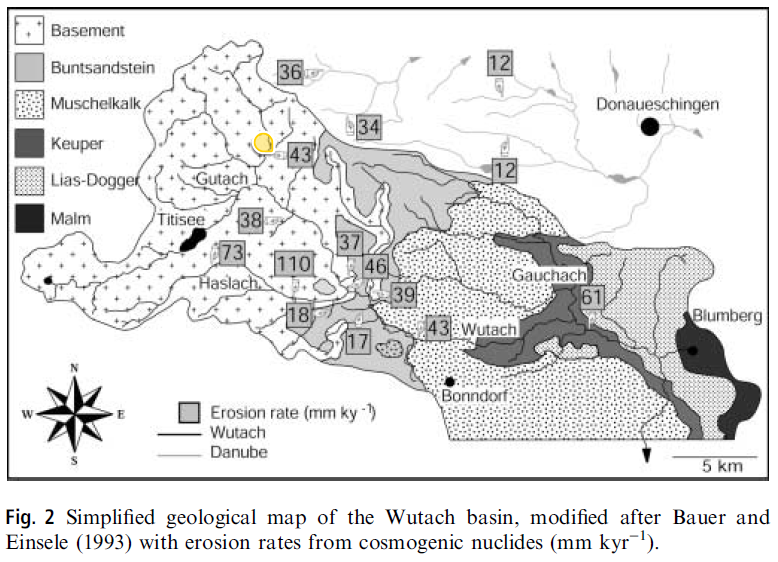*Morel et al. 2003*

"Normal" millenial time-scale background erosion rates above the capture knickpoints are ~50 mm/ka (0.05 mm/yr) and thus post-capture erosion rates are about 30 times higher than the long-term average! This is the effect of drainage captures on landscape evolution. Drainage reorganization can drive large transient waves in erosion. 